close all

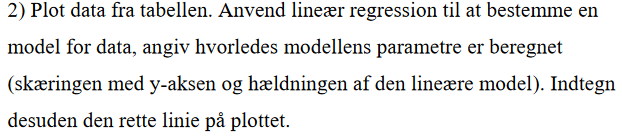

antal=[28,46,44,63,104,148,172,187,223,236];
year=1985:1:1994

year =         1985        1986        1987        1988        1989        1990        1991        1992        1993        1994



figure(1)
scatter(year, antal)
hold on
%figure(2)
P = polyfit(year,antal,1)

P =    1.0e+04 *

    0.0025   -5.0481


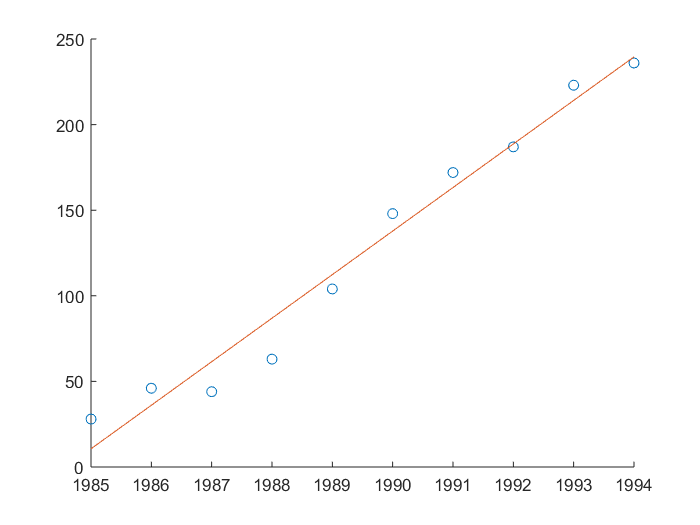

pfit=P(1)*year+P(2);
plot(year,pfit)

r = antal - (P(1)*year+P(2))

r =    17.3636    9.9273  -17.5091  -23.9455   -8.3818   10.1818    8.7455   -1.6909    8.8727   -3.5636


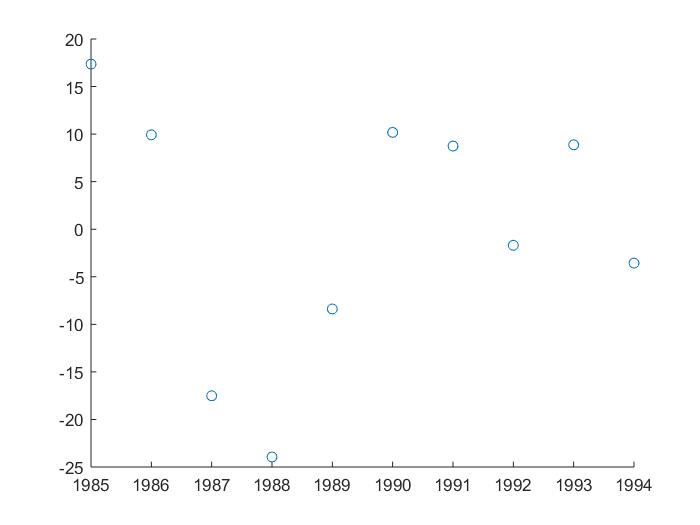

figure(2)
scatter(year,r)

% Estimer variansen
var = (1/(length(r)-2))*sum(r.^2)

var = 203.0864


% Beregn standardafvigelsen
sigma = sqrt(var)

sigma = 14.2508


% Find t0
t0 = tinv(0.975,length(r)-2)

t0 = 2.3060

delta = sum(year.^2) - (1/length(year))*sum(year)^2

delta = 82.5000

d_minus = P(1) - t0 * sqrt(var/delta)

d_minus = 21.8183

d_plus = P(1) + t0 * sqrt(var/delta)

d_plus = 29.0544

% Konfidensintervallet er tæt, og residualplottet viser at værdierne er fordelt ens omkring 0.
% Derfor er antagelsen rimelig

% Negative årstal duer ikke.